# doble_integracion_ddi

performs the integral double of a sampled signal with the de-drifted integration (DDI method) 

## Syntax

pos=doble_integracion_ddi(acc,freq)

## Description

`pos=doble_integracion_ddi(acc,freq)` performs the integral double of a signal `acc` sampled at `freq` Hz with the the optimally filtered integration (OFI method). 

It encompasses the subtraction of a weighted mean function of data samples, previous to each of both integrations. The acceleration drift function is computed by averaging a few initial and final accelerometry samples and by removing a lineal interpolation between both values from the original signal. The size of both sets of samples is empirically selected. 		

	  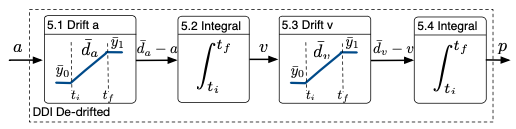		

The velocity drift function is based on the assumption of zero velocity at the beginning and end of the cycle, and a lineal function from zero to the mean of the last velocity samples is subtracted from to achieve it. 

More information: 

Rampp, A.; Barth, J.; Schuelein, S.; Gassmann, K.G.; Klucken, J.; Eskofier, B.M. Inertial Sensor-Based 							Stride Parameter Calculation From Gait Sequences in Geriatric Patients. *IEEE Trans. Biomed. Eng. ***2015**, 							*62*, 1089–1097. 												

## Examples

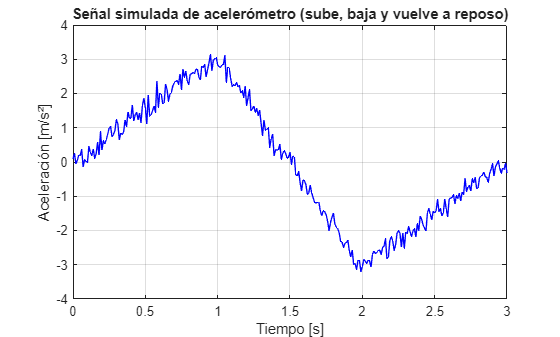

% Simulamos una señal de acelerómetro que sube, baja y vuelve a reposo con ruido
fs = 100;                     % Frecuencia de muestreo [Hz]
t = 0:1/fs:3;                 % Duración de 3 segundos
n = length(t);

% Creamos una forma de aceleración: subida, bajada, reposo
fase1 = linspace(0, 3, round(n/3));       % subida
fase2 = linspace(3, -3, round(n/3));      % bajada
fase3 = linspace(-3, 0, n - 2*round(n/3));% vuelta a reposo
acc_real = [fase1 fase2 fase3];           % concatenamos

% Añadimos ruido gaussiano para simular el sensor
ruido = 0.2*randn(1, n);
acc = (acc_real + ruido)';

% Visualizamos la señal simulada
figure
plot(t, acc, 'b')
xlabel('Tiempo [s]')
ylabel('Aceleración [m/s²]')
title('Señal simulada de acelerómetro (sube, baja y vuelve a reposo)')
grid on

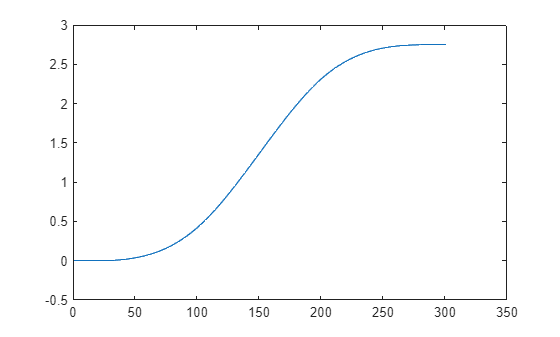

plot(doble_integracion_ddi(acc,100));